# Geometric model for bernoulli trials

## Expected number of boxes to open to find the charizard card

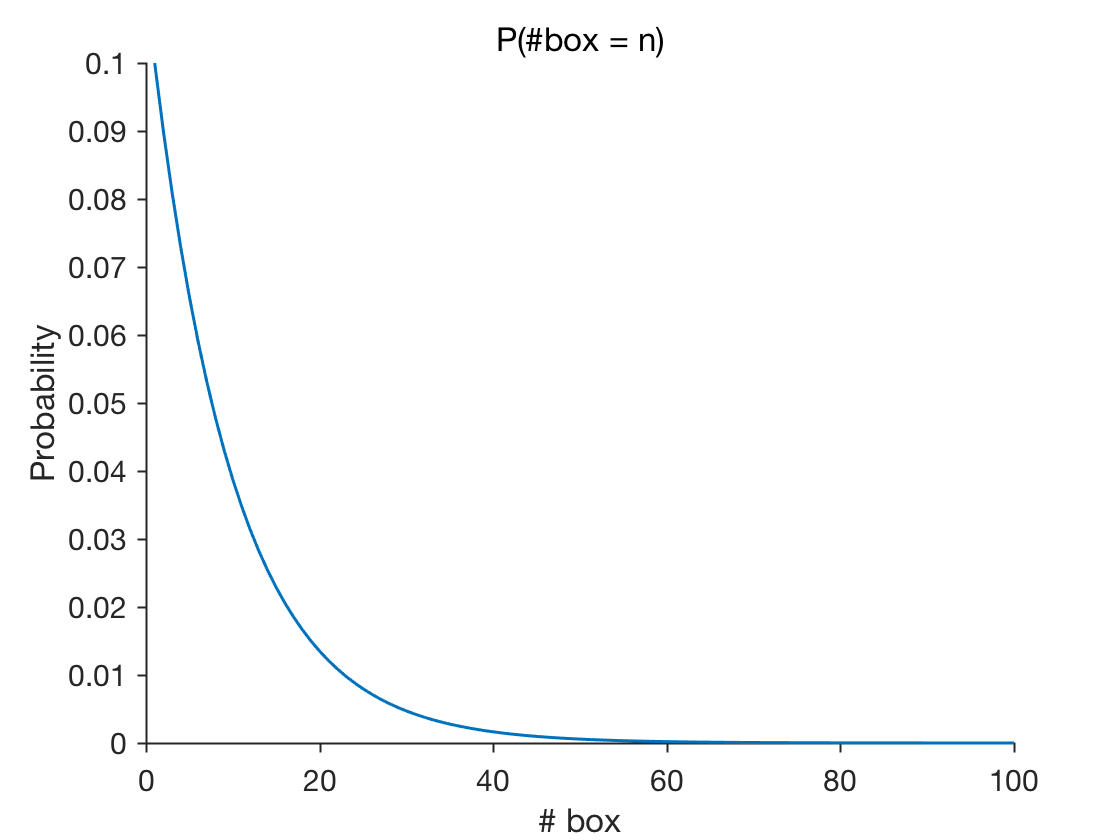

p = 0.1;
q = 1-p;
n = 1:100;
p_n_box = q.^(n-1)*p;
plot(p_n_box, 'linewidth', 1.5);
title('P(#box = n)')
xlabel('# box')
ylabel('Probability');
set(gca, 'linewidth', 1, 'fontsize', 15, 'tickdir', 'out');
set(gcf, 'color', 'w'); 
box off;


str = 'The expected number of boxes to open to find the charizard card is';
fprintf('\n%s %d.\n', str, ceil(sum(n.*p_n_box)));


The expected number of boxes to open to find the charizard card is 10.


## Plot geometric probability

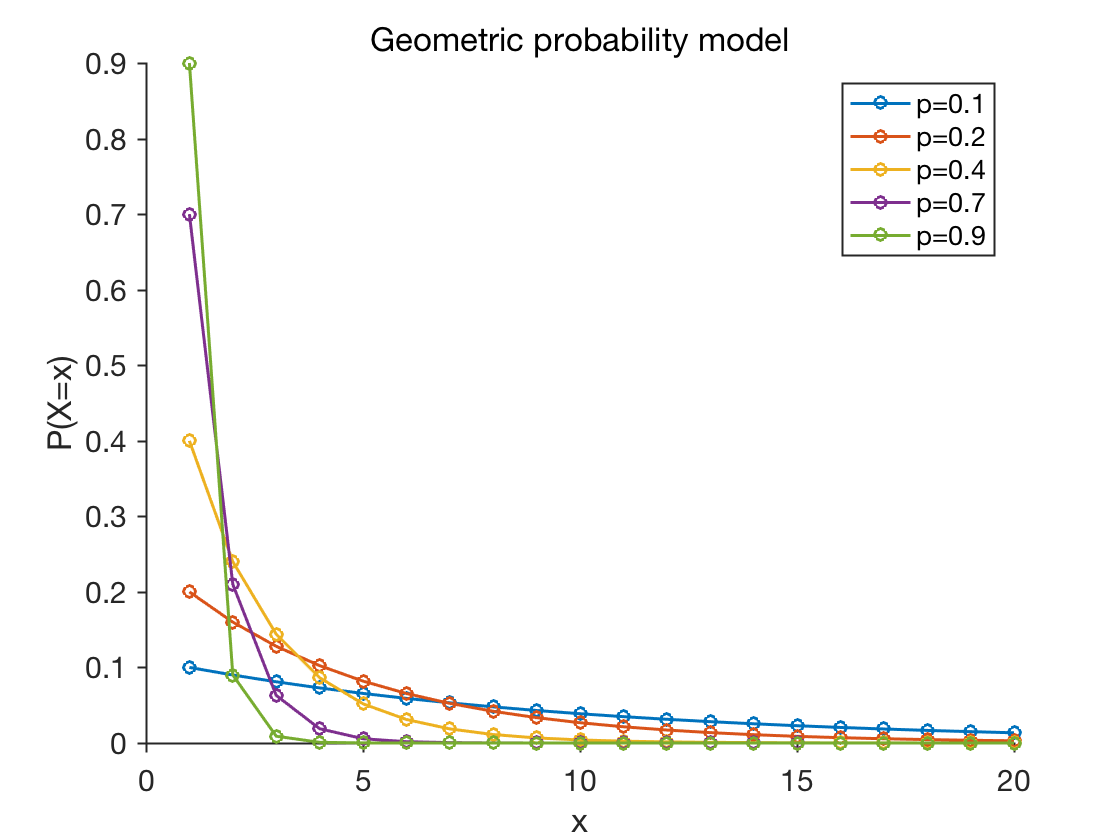

close all;
p_all = [.1 .2 .4 .7 .9];
legend_cell = cell(numel(p_all),1);

figure; 
for i = 1:numel(p_all)
    p = p_all(i);
    q = 1-p;
    n = 1:20;
    p_n_box = q.^(n-1)*p;
    hold on;
    plot(p_n_box, 'o-', 'linewidth', 1.5);
    legend_cell{i} = sprintf('p=%0.1f', p);
end

title('Geometric probability model')
xlabel('x')
ylabel('P(X=x)');

legend(legend_cell);

set(gca, 'linewidth', 1, 'fontsize', 15, 'tickdir', 'out');
set(gcf, 'color', 'w'); 
box off;